# よくみる図generator（途中）

慣性系x軸方向に宇宙機，月，太陽が存在すると仮定．

ベクトルとして外乱を計算して，ノルムをプロット

clc
clear

const = orbitConst;

mu = const.GE;
J2 = const.J2;

h = 0:10:43000; % altitude
r = const.RE + h; % distance from the center of the Earth
r =  r(:);
rVec = [ones(length(r),1) zeros(length(r),2)] .* r;
x = rVec(:,1);
y = rVec(:,2);
z = rVec(:,3);

% longitude
phi = 0;

sunPos = au2km(1, const) .* [1 0 0];
moonPos = 384400 .* [1 0 0]; % km

sat.m = 100;


## Earth

aEarth = -const.GE ./ r.^3 .* rVec;

### 
$$J_2
$$


dUdr = J2 .* mu ./ r.^2 .* 3 .* (const.RE ./ r).^2 ./ 2 .* (3 * sin(phi)^2 - 1);
dUdphi = J2 .* mu ./ r .* (const.RE ./ r).^2 * 3 * sin(phi) * sqrt(1 - sin(phi)^2);
dUdlam = 0;

aJ2x = (1 ./ r .* dUdr - z ./ r.^2 ./ sqrt(x.^2 + y.^2) .* dUdphi) .* x - y ./ (x.^2 + y.^2) .* dUdlam;
aJ2y = (1 ./ r .* dUdr - z ./ r.^2 ./ sqrt(x.^2 + y.^2) .* dUdphi) .* y + x ./ (x.^2 + y.^2) .* dUdlam;
aJ2z = z ./ r .* dUdr + sqrt(x.^2 + y.^2) ./ r.^2 .* dUdphi;

aJ2 = [aJ2x, aJ2y, aJ2z];

## Sun

% relative position vector from satellite to sun at inertial frame
rSC2s = sunPos - rVec; % nx3

% at inertial frame
aSun = const.GS .* (rSC2s ./ vecnorm(rSC2s,2,2).^3 - sunPos ./ vecnorm(sunPos,2,2).^3);


## Moon

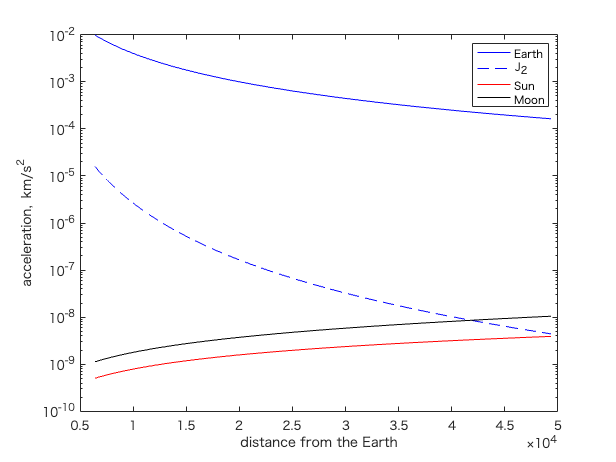

% relative position vector from satellite to moon at inertial frame
rSC2m = moonPos - rVec; % nx3

% at inertial frame
aMoon = const.GM .* (rSC2m ./ vecnorm(rSC2m,2,2).^3 - moonPos ./ vecnorm(moonPos,2,2).^3);


figure
semilogy(r, vecnorm(aEarth, 2, 2), 'b'), hold on
semilogy(r, vecnorm(aJ2, 2, 2), 'b--')
semilogy(r, vecnorm(aSun, 2, 2), 'r')
semilogy(r, vecnorm(aMoon, 2, 2), 'k')
legend('Earth', 'J_2', 'Sun', 'Moon')
xlabel('distance from the Earth')
ylabel('acceleration, km/s^2')